% Read in file, define inital parameters and variables
clear all;
%fig=gcf;
%fig.Position(4)=210;
file = "22steps.mat";
s_length = 0.5;
truth = 6;

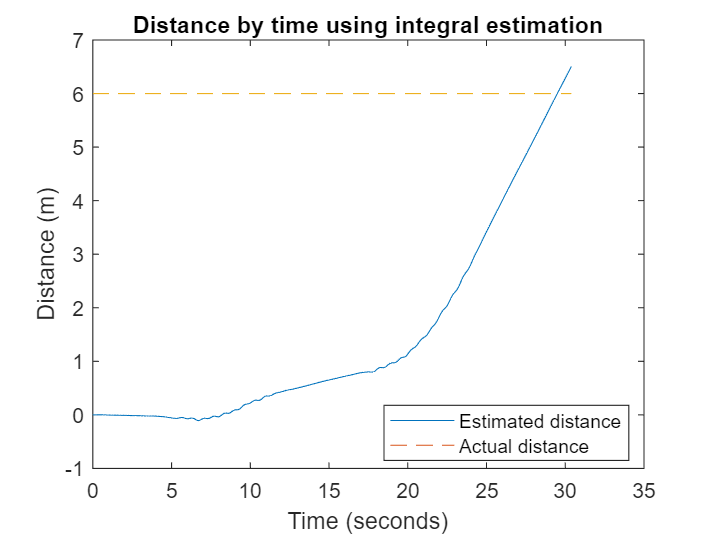

[t, a_norm] = get_a(file);
e_int = int_est(a_norm,t,truth);

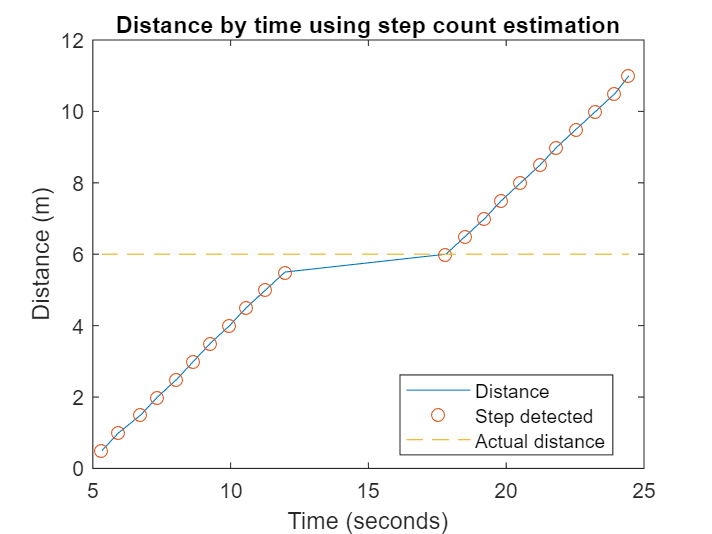

nstep = step_count(file,s_length,truth);

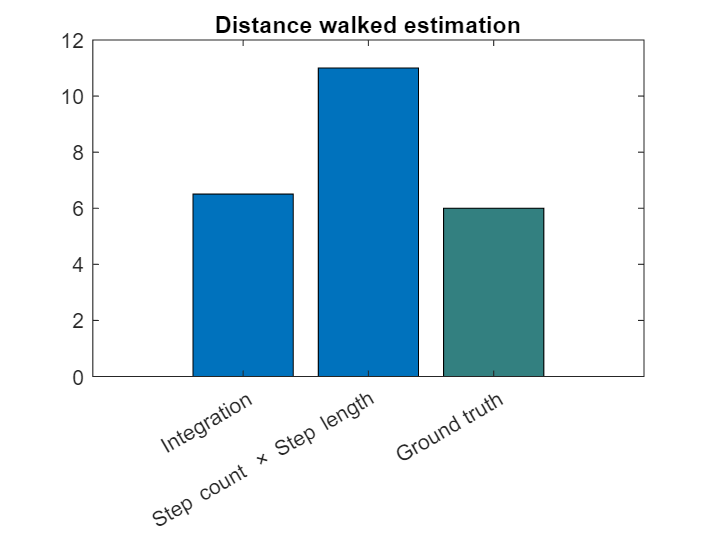

e_step = nstep*s_length;

b = bar([e_int e_step truth]);
title('Distance walked estimation');
xticks([1 2 3]);
xticklabels({'Integration','Step count \times Step length','Ground truth'});
b.FaceColor='flat';
b.CData(end,:) = [0.2 0.5 0.5];

function [t,a_norm] = get_a(file)
    a = load(file).Acceleration;
    calibration_time = 3;
    
    % Is the phone position stationary?
    stationary = true;
    
    % In case phone position is stationary, set up the gravity
    gravity_x = 0;
    gravity_y = 0;
    gravity_z = 9.8;
    gravity = sqrt(gravity_x^2 + gravity_y^2 + gravity_z^2);
    
    t = a.Timestamp.Second - a.Timestamp.Second(1);
    t(t<0) = t(t<0) + 60;
    % Sampling frequency
    f=1/(t(2)-t(1));
    
    % Calibration
    calib_idx = round(calibration_time * f);
    tc = t(1:calib_idx);
    xc = a.X(1:calib_idx);
    yc = a.Y(1:calib_idx);
    zc = a.Z(1:calib_idx);
    
    if stationary
        % Use linear regression to get the bias values
        T = [ones(length(tc),1) tc];
        line_x = T\xc;
        X0 = line_x(1) - gravity_x;
        line_y = T\yc;
        Y0 = line_y(1) - gravity_y;
        line_z = T\zc;
        Z0 = line_z(1) - gravity_z;
    else
        [X0, Y0, Z0] = deal(0,0,0);
    end
    % Norm by time
    a_norm = ((a.X-X0).^2 + (a.Y-Y0).^2 + (a.Z-Z0).^2).^0.5;
end

function d = int_est(a_norm,t,truth)
    da = cumtrapz(t,a_norm-9.8);%cumsum((a_norm-9.8)/f);
    dv = cumtrapz(t,da);%cumsum(da/f);
    d = dv(end);
    plot(t,dv,t,truth*ones(length(t)),'--');
    title('Distance by time using integral estimation');
    legend('Estimated distance','Actual distance','Location','best');
    xlabel('Time (seconds)');
    ylabel('Distance (m)');
end

function l = step_count(file,s_length,truth)
    a = load(file).Acceleration;
    calibration_time = 3;
    
    % Is the phone position stationary?
    stationary = true;
    
    % In case phone position is stationary, set up the gravity
    gravity_x = 0;
    gravity_y = 0;
    gravity_z = 9.8;
    gravity = sqrt(gravity_x^2 + gravity_y^2 + gravity_z^2);
    
    t = a.Timestamp.Second - a.Timestamp.Second(1);
    t(t<0) = t(t<0) + 60;
    % Sampling frequency
    f=1/(t(2)-t(1));
    
    % Calibration
    calib_idx = round(calibration_time * f);
    tc = t(1:calib_idx);
    xc = a.X(1:calib_idx);
    yc = a.Y(1:calib_idx);
    zc = a.Z(1:calib_idx);
    
    if stationary
        % Use linear regression to get the bias values
        T = [ones(length(tc),1) tc];
        line_x = T\xc;
        X0 = line_x(1) - gravity_x;
        line_y = T\yc;
        Y0 = line_y(1) - gravity_y;
        line_z = T\zc;
        Z0 = line_z(1) - gravity_z;
    else
        [X0, Y0, Z0] = deal(0,0,0);
    end
    % Norm by time
    a_norm = ((a.X-X0).^2 + (a.Y-Y0).^2 + (a.Z-Z0).^2).^0.5;

    a_tf = fft(a_norm - gravity);
    a_tf = fftshift(a_tf);
    L = length(a_norm);
    freqs = f/L * linspace(0,L-1,L) - f/2;
    
    [pks,loc] = findpeaks(abs(a_tf), freqs);
    l = ceil(length(loc)/2);
    [mu,sig] = normal_dist(loc(l:end),pks(l:end));
    
    % Set up filter
    fmin = mu - 3*sig;
    fmax = mu + 3.5*sig;
    % Filter
    a_filtered = bandpass(a_norm,[fmin,fmax],f);
    
    % Use calibration segment to identify max prominence noise
    [~,~,~,pc] = findpeaks(a_filtered(1:calib_idx), freqs(1:calib_idx), 'SortStr','descend');
    
    % Ensure margin is large enough to prevent noise peaks
    b_norm = (X0^2+Y0^2+Z0^2)^0.5;
    if b_norm > 0.2 margin=b_norm; else margin=0.2; end 
    
    minP = pc(1) + margin; % Add bias norm as safe margin
    
    % Get the highest likely step frequency in the data
    maxStepFreq = mu + 4*sig;
    
    % Set up peak-finding parameters
    settings = struct('MinPeakDistance', 1/maxStepFreq, ...
                      'MinPeakProminence', minP);
    
    % Find peaks that correspond to steps
    [ps,lps] = findpeaks(a_filtered,t,settings);
    l = length(ps);

    dist = cumsum(ones(1,length(lps))) * s_length;
    plot(lps,dist,'-',lps,dist,'o',lps,truth*ones(length(lps)),'--');
    legend('Distance','Step detected','Actual distance','Location','best');
    title('Distance by time using step count estimation');
    xlabel('Time (seconds)');
    ylabel('Distance (m)');
end

function [mu,sig] = normal_dist(x,p)
    sum_x = 0;
    sum_var = 0;

    sum_p = sum(p);
    for i=1:length(x)
        sum_x = sum_x + x(i)*p(i)/sum_p;
    end
    mu = sum_x;
    for i=1:length(x)
        sum_var = sum_var + (x(i)-mu)^2;
    end
    sig = sqrt(sum_var/sum_p);
end